clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada ArfadaCaso1 ArfadaCaso2 ArfadaCaso3 CabeceoCaso1 CabeceoCaso2 CabeceoCaso3 BalanceoCaso1 BalanceoCaso2 BalanceoCaso3
largoB=0.4;
largoM=0.2;
AlturaPlaca=0.55;
PosXBiela=0.1;
PosYBiela=-0.4;
PosXEje=0;
PosYEje=-0.4;
PosZEje=0.2; 

## Arfada

### Caso 1: Arfada simple

tiempo=linspace(0,double(tMax_a),80)';
balanceo=0;
cabeceo=0;
arfada=Fz_arfada;


%theta1
FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaArfadaW=diff(FthetaArfada);
FthetaArfadaAlpha=diff(FthetaArfadaW);
%plot(t,Ftheta())

#### Valores arfada

angulosArfada=double(subs(FthetaArfada,tiempo));
VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));

ArfadaCaso1=table(tiempo,angulosArfada,VelocidadAngularArfada,AceleracionAngularArfada)

ArfadaCaso1 = 80×4 table
     tiempo      angulosArfada    VelocidadAngularArfada    AceleracionAngularArfada
    _________    _____________    ______________________    ________________________

            0      -0.19234                   NaN                       NaN         
    0.0040415      -0.19233             0.0067155                    3.3233         
    0.0080829      -0.19227              0.026861                    6.6461         
     0.012124       -0.1921              0.060433                    9.9672         
     0.016166      -0.19176               0.10742                    13.285         
     0.020207      -0.19121                0.1678                    16.596         
     0.024249      -0.19039               0.24155                    19.897         
      0.02829      -0.18924               0.32861                    23.1

#### Gráficas arfada

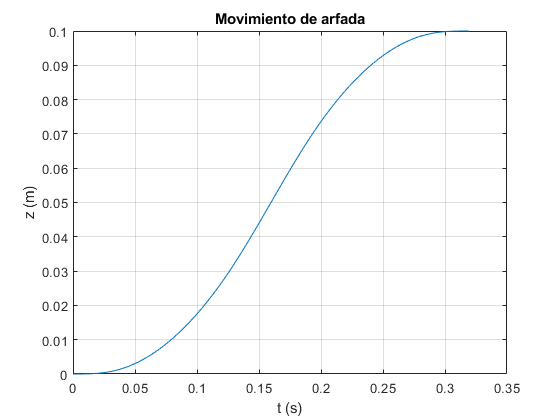

figure()
plot(tiempo,arfada(tiempo))
title('Movimiento de arfada')
grid on
xlabel('t (s)')
ylabel('z (m)')

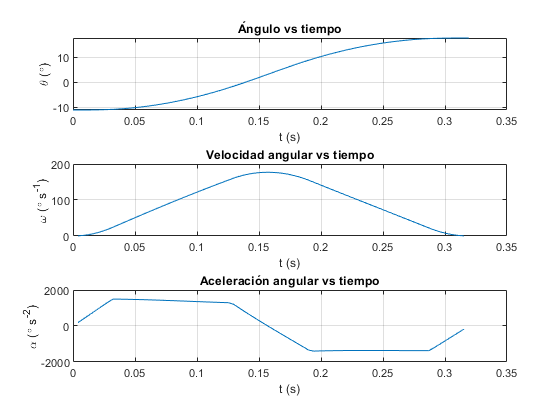


figure('Name','Cinematica manivela en arfada caso 1')
subplot(3,1,1)
plot(tiempo,angulosArfada.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularArfada.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularArfada.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 2: Balanceo y cabeceo máximos

tiempo=linspace(0,double(tMax_a),80)';
balanceo=15*pi/180;
cabeceo=18*pi/180;
arfada=Fz_arfada;

FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaArfadaW=diff(FthetaArfada);
FthetaArfadaAlpha=diff(FthetaArfadaW);


#### Valores arfada

angulosArfada=double(subs(FthetaArfada,tiempo));
VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));

ArfadaCaso2=table(tiempo,angulosArfada,VelocidadAngularArfada,AceleracionAngularArfada)

ArfadaCaso2 = 80×4 table
     tiempo      angulosArfada    VelocidadAngularArfada    AceleracionAngularArfada
    _________    _____________    ______________________    ________________________

            0       -1.1502                   NaN                       NaN         
    0.0040415       -1.1501              0.014287                    7.0701         
    0.0080829         -1.15               0.05714                    14.135         
     0.012124       -1.1496               0.12851                    21.181         
     0.016166       -1.1489               0.22829                    28.187         
     0.020207       -1.1477               0.35625                     35.12         
     0.024249        -1.146               0.51202                    41.944         
      0.02829       -1.1436               0.69507                    48.6

#### Gráficas arfada

figure()
plot(tiempo,arfada(tiempo))
title('Movimiento de arfada')
grid on
xlabel('t (s)')
ylabel('z (m)')

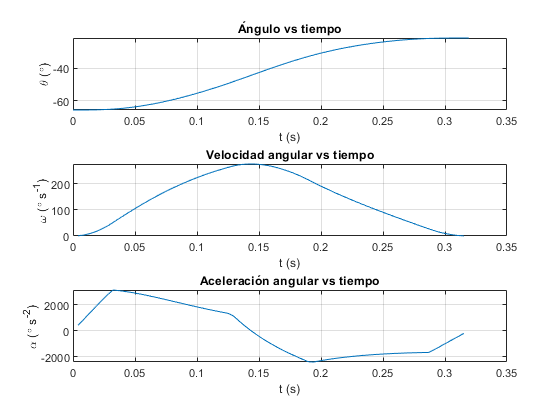


figure('Name','Cinematica manivela en arfada caso 2')
subplot(3,1,1)
plot(tiempo,angulosArfada.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularArfada.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularArfada.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 3: Balanceo y cabeceo mínimos

tiempo=linspace(0,double(tMax_a),80)';
balanceo=-15*pi/180;
cabeceo=-18*pi/180;
arfada=Fz_arfada;

%theta1
FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaArfadaW=diff(FthetaArfada);
FthetaArfadaAlpha=diff(FthetaArfadaW);
%plot(t,Ftheta())

#### Valores arfada

angulosArfada=double(subs(FthetaArfada,tiempo));
VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));

ArfadaCaso3=table(tiempo,angulosArfada,VelocidadAngularArfada,AceleracionAngularArfada)

ArfadaCaso3 = 80×4 table
     tiempo      angulosArfada    VelocidadAngularArfada    AceleracionAngularArfada
    _________    _____________    ______________________    ________________________

            0       0.48089                   NaN                       NaN         
    0.0040415        0.4809              0.006376                    3.1553         
    0.0080829       0.48096              0.025505                     6.311         
     0.012124       0.48112              0.057389                    9.4681         
     0.016166       0.48144               0.10204                    12.628         
     0.020207       0.48196               0.15947                    15.793         
     0.024249       0.48275               0.22971                    18.967         
      0.02829       0.48384               0.31279                    22.1

#### Gráficas arfada

figure()
plot(tiempo,arfada(tiempo))
title('Movimiento de arfada')
grid on
xlabel('t (s)')
ylabel('z (m)')

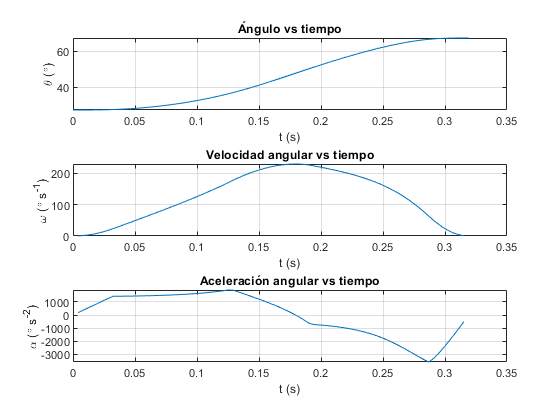


figure('Name','Cinematica manivela en arfada caso 3')
subplot(3,1,1)
plot(tiempo,angulosArfada.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularArfada.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularArfada.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

## Cabeceo

### Caso 1: Balanceo y arfada nula

tiempo=linspace(0,double(tMax_c),80)';
balanceo=0; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0; %valor de arfada

%theta1
FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaCabeceoW=diff(FthetaCabeceo);
FthetaCabeceoAlpha=diff(FthetaCabeceoW);
%plot(t,Ftheta())

#### Valores cabeceo

angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));

CabeceoCaso1=table(tiempo,angulosCabeceo,VelocidadAngularCabeceo,AceleracionAngularCabeceo)

CabeceoCaso1 = 80×4 table
     tiempo      angulosCabeceo    VelocidadAngularCabeceo    AceleracionAngularCabeceo
    _________    ______________    _______________________    _________________________

            0      -0.025591                    NaN                        NaN         
    0.0070949      -0.025596             -0.0023408                   -0.65985         
      0.01419      -0.025635             -0.0093633                    -1.3197         
     0.021285       -0.02574              -0.021068                    -1.9798         
      0.02838      -0.025945              -0.037457                    -2.6402         
     0.035475      -0.026283              -0.058533                    -3.3011         
      0.04257      -0.026787              -0.084302                     -3.963         
     0.049664       -0.02749               -0

#### Gráficas cabeceo

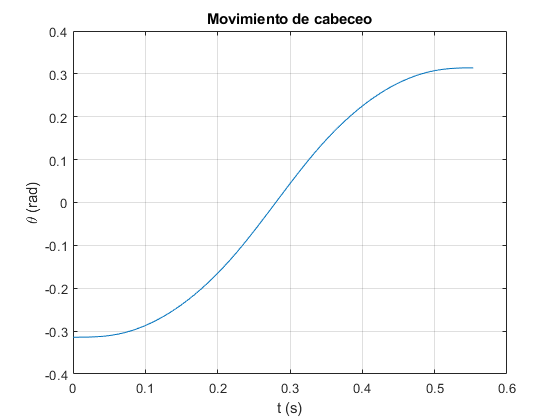

figure()
plot(tiempo,cabeceo(tiempo))
title('Movimiento de cabeceo')
xlabel('t (s)')
ylabel('\theta (rad)')
grid on

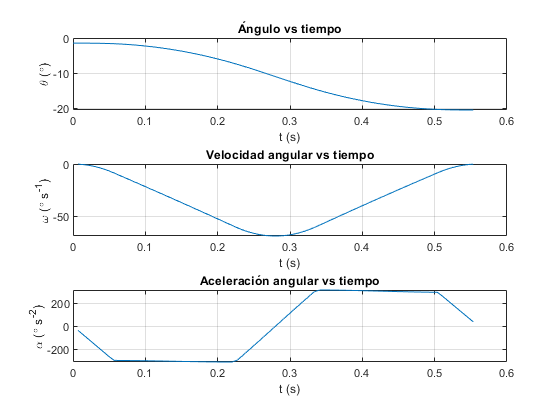

figure('Name','Cinematica manivela en cabeceo caso 1')
subplot(3,1,1)
plot(tiempo,angulosCabeceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularCabeceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularCabeceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 2: Balanceo máximo, arfada nula

tiempo=linspace(0,double(tMax_c),80)';
balanceo=15*pi/180; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0; %valor de arfada

%theta1
FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaCabeceoW=diff(FthetaCabeceo);
FthetaCabeceoAlpha=diff(FthetaCabeceoW);
%plot(t,Ftheta())

#### Valores cabeceo

angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));

CabeceoCaso2=table(tiempo,angulosCabeceo,VelocidadAngularCabeceo,AceleracionAngularCabeceo)

CabeceoCaso2 = 80×4 table
     tiempo      angulosCabeceo    VelocidadAngularCabeceo    AceleracionAngularCabeceo
    _________    ______________    _______________________    _________________________

            0       -0.63172                    NaN                        NaN         
    0.0070949       -0.63172             -0.0030679                   -0.86482         
      0.01419       -0.63177              -0.012272                    -1.7298         
     0.021285       -0.63191              -0.027615                    -2.5953         
      0.02838       -0.63218              -0.049103                    -3.4621         
     0.035475       -0.63262              -0.076747                    -4.3311         
      0.04257       -0.63328               -0.11057                    -5.2035         
     0.049664       -0.63421                -

#### Gráficas cabeceo

figure()
plot(tiempo,cabeceo(tiempo))
title('Movimiento de cabeceo')
xlabel('t (s)')
ylabel('\theta (rad)')
grid on

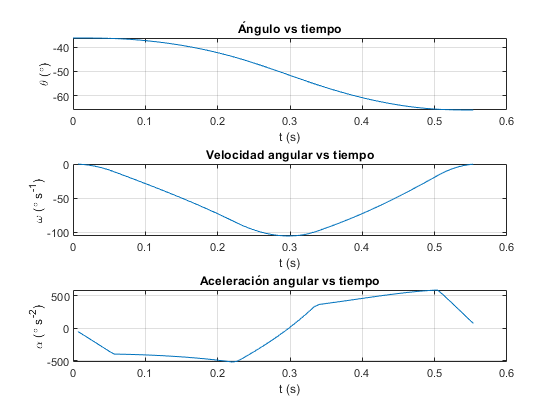

figure('Name','Cinematica manivela en cabeceo caso 1')
subplot(3,1,1)
plot(tiempo,angulosCabeceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularCabeceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularCabeceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 3: Balanceo minimo, arfada máxima 

tiempo=linspace(0,double(tMax_c),80)';
balanceo=-15*pi/180; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0.1; %valor de arfada


FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaCabeceoW=diff(FthetaCabeceo);
FthetaCabeceoAlpha=diff(FthetaCabeceoW);


#### Valores cabeceo

angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));

CabeceoCaso3=table(tiempo,angulosCabeceo,VelocidadAngularCabeceo,AceleracionAngularCabeceo)

CabeceoCaso3 = 80×4 table
     tiempo      angulosCabeceo    VelocidadAngularCabeceo    AceleracionAngularCabeceo
    _________    ______________    _______________________    _________________________

            0        1.1725                     NaN                        NaN         
    0.0070949        1.1725               -0.005937                    -1.6735         
      0.01419        1.1724                -0.02374                    -3.3442         
     0.021285        1.1721               -0.053367                     -5.005         
      0.02838        1.1716                -0.09471                    -6.6444         
     0.035475        1.1708                -0.14756                    -8.2466         
      0.04257        1.1695                 -0.2116                    -9.7925         
     0.049664        1.1678                -0

#### Gráficas cabeceo

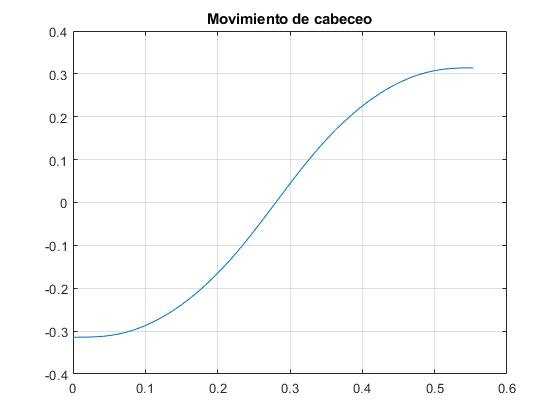

figure()
plot(tiempo,cabeceo(tiempo))
title('Movimiento de cabeceo')
grid on

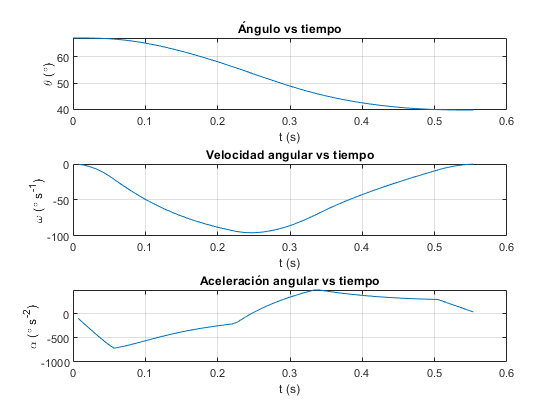

figure('Name','Cinematica manivela en cabeceo caso 2')
subplot(3,1,1)
plot(tiempo,angulosCabeceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularCabeceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularCabeceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

## Balanceo

### Caso 1: Cabeceo y arfada nula 

tiempo=linspace(0,double(tMax_b),80)';
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=0; %valor cabeceo en radianes
arfada=0; %valor de arfada


FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaBalanceoW=diff(FthetaBalanceo);
FthetaBalanceoAlpha=diff(FthetaBalanceoW);


#### Valores balanceo

angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));

BalanceoCaso1=table(tiempo,angulosBalanceo,VelocidadAngularBalanceo,AceleracionAngularBalanceo)

BalanceoCaso1 = 80×4 table
     tiempo      angulosBalanceo    VelocidadAngularBalanceo    AceleracionAngularBalanceo
    _________    _______________    ________________________    __________________________

            0        0.32526                     NaN                         NaN          
    0.0064768        0.32524               -0.007829                     -2.4176          
     0.012954        0.32512               -0.031316                      -4.835          
      0.01943         0.3248               -0.070459                     -7.2521          
     0.025907        0.32418                -0.12525                     -9.6685          
     0.032384        0.32314                 -0.1957                     -12.084          
     0.038861        0.32161                -0.28178                     -14.497          
     0.045337    

#### Gráficas balanceo

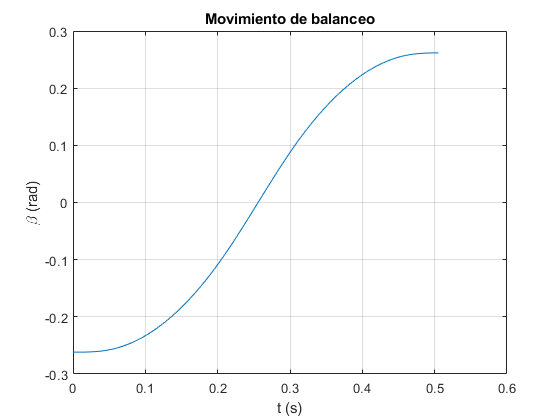


figure()
plot(tiempo,balanceo(tiempo))
title('Movimiento de balanceo')
grid on
xlabel('t (s)')
ylabel('\beta (rad)')

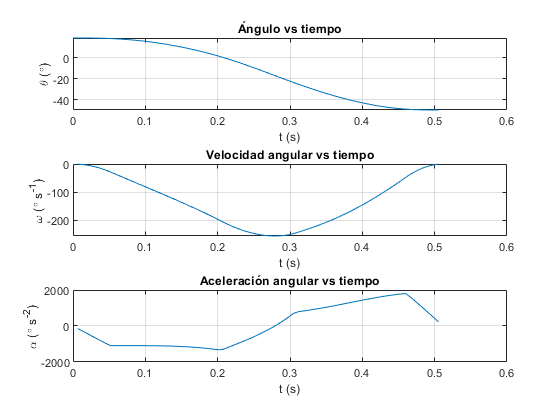


figure('Name','Cinematica manivela en balanceo caso 1')
subplot(3,1,1)
plot(tiempo,angulosBalanceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularBalanceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularBalanceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 2: Cabeceo máximo, arfada nula 

tiempo=linspace(0,double(tMax_b),80)';
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=18*pi/180; %valor cabeceo en radianes
arfada=0; %valor de arfada

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaBalanceoW=diff(FthetaBalanceo);
FthetaBalanceoAlpha=diff(FthetaBalanceoW);


#### Valores balanceo

angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));

BalanceoCaso2=table(tiempo,angulosBalanceo,VelocidadAngularBalanceo,AceleracionAngularBalanceo)

BalanceoCaso2 = 80×4 table
     tiempo      angulosBalanceo    VelocidadAngularBalanceo    AceleracionAngularBalanceo
    _________    _______________    ________________________    __________________________

            0        0.18509                      NaN                        NaN          
    0.0064768        0.18507               -0.0078598                    -2.4271          
     0.012954        0.18495                 -0.03144                    -4.8544          
      0.01943        0.18463                -0.070742                    -7.2823          
     0.025907          0.184                 -0.12577                    -9.7116          
     0.032384        0.18296                 -0.19655                    -12.144          
     0.038861        0.18142                 -0.28308                     -14.58          
     0.045337    

#### Gráficas balanceo


figure()
plot(tiempo,balanceo(tiempo))
title('Movimiento de balanceo')
grid on
xlabel('t (s)')
ylabel('\beta (rad)')

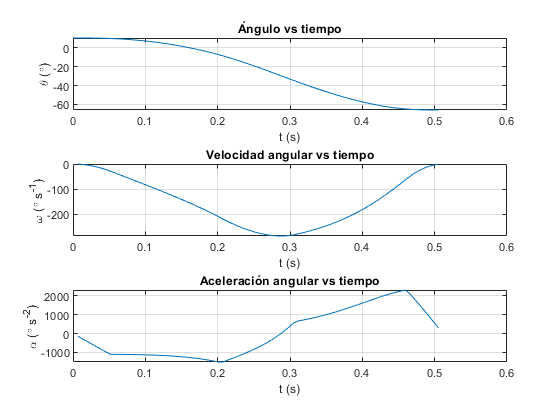


figure('Name','Cinematica manivela en balanceo caso 1')
subplot(3,1,1)
plot(tiempo,angulosBalanceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularBalanceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularBalanceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 3: Cabeceo minimo, arfada máxima

tiempo=linspace(0,double(tMax_b),80)';
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=-18*pi/180;
arfada=0.1; %valor de arfada

%theta1
FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaBalanceoW=diff(FthetaBalanceo);
FthetaBalanceoAlpha=diff(FthetaBalanceoW);
%plot(t,Ftheta())

#### Valores balanceo

angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));

BalanceoCaso3=table(tiempo,angulosBalanceo,VelocidadAngularBalanceo,AceleracionAngularBalanceo)

BalanceoCaso3 = 80×4 table
     tiempo      angulosBalanceo    VelocidadAngularBalanceo    AceleracionAngularBalanceo
    _________    _______________    ________________________    __________________________

            0        1.1725                      NaN                         NaN          
    0.0064768        1.1725                -0.022752                     -7.0237          
     0.012954        1.1721                -0.090886                         -14          
      0.01943        1.1712                 -0.20376                     -20.812          
     0.025907        1.1694                 -0.35972                     -27.273          
     0.032384        1.1665                 -0.55578                     -33.153          
     0.038861        1.1621                 -0.78741                     -38.219          
     0.045337    

#### Gráficas balanceo

figure()
plot(tiempo,balanceo(tiempo))
xlabel('t (s)')
ylabel('\beta (rad)')
title('Movimiento de balanceo')
grid on

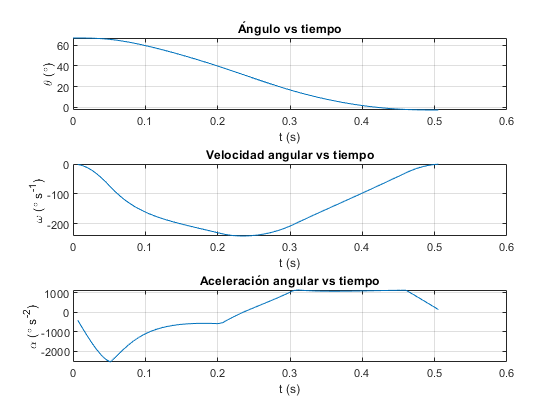

ArfadaCaso1 = 80×4 table
     tiempo      angulosArfada    VelocidadAngularArfada    AceleracionAngularArfada
    _________    _____________    ______________________    ________________________

            0      -0.19234                   NaN                       NaN         
    0.0040415      -0.19233             0.0067155                    3.3233         
    0.0080829      -0.19227              0.026861                    6.6461         
     0.012124       -0.1921              0.060433                    9.9672         
     0.016166      -0.19176               0.10742                    13.285         
     0.020207      -0.19121                0.1678                    16.596         
     0.024249      -0.19039               0.24155                    19.897         
      0.02829      -0.18924               0.32861                    23.1

MAC1 = 80×2 table
      Var1         Var2  
    _________    ________

            0    -0.19234
    0.0040415    -0.19233
    0.0080829    -0.19227
     0.012124     -0.1921
     0.016166    -0.19176
     0.020207    -0.19121
     0.024249    -0.19039
      0.02829    -0.18924
     0.032332    -0.18772
     0.036373    -0.18577
     0.040415     -0.1834
     0.044456     -0.1806
     0.048498    -0.17738
     0.052539    -0.17374
      0.05658    -0.16969
     0.060622    -0.16521


MAC1 = 80×2 table
    [Tangents]    cambiar 
    __________    ________

            0     -0.19234
    0.0040415     -0.19233
    0.0080829     -0.19227
     0.012124      -0.1921
     0.016166     -0.19176
     0.020207     -0.19121
     0.024249     -0.19039
      0.02829     -0.18924
     0.032332     -0.18772
     0.036373     -0.18577
     0.040415      -0.1834
     0.044456      -0.1806
     0.048498     -0.17738
     0.052539     -0.17374
      0.05658     -0.16969
     0.060622     -0.16521


MAC2 = 80×2 table
      Var1        Var2  
    _________    _______

            0    -1.1502
    0.0040415    -1.1501
    0.0080829      -1.15
     0.012124    -1.1496
     0.016166    -1.1489
     0.020207    -1.1477
     0.024249     -1.146
      0.02829    -1.1436
     0.032332    -1.1403
     0.036373    -1.1363
     0.040415    -1.1313
     0.044456    -1.1254
     0.048498    -1.1188
     0.052539    -1.1113
      0.05658    -1.1029
     0.060622    -1.0938


MAC2 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     -1.1502
    0.0040415     -1.1501
    0.0080829       -1.15
     0.012124     -1.1496
     0.016166     -1.1489
     0.020207     -1.1477
     0.024249      -1.146
      0.02829     -1.1436
     0.032332     -1.1403
     0.036373     -1.1363
     0.040415     -1.1313
     0.044456     -1.1254
     0.048498     -1.1188
     0.052539     -1.1113
      0.05658     -1.1029
     0.060622     -1.0938


MAC3 = 80×2 table
      Var1        Var2  
    _________    _______

            0    0.48089
    0.0040415     0.4809
    0.0080829    0.48096
     0.012124    0.48112
     0.016166    0.48144
     0.020207    0.48196
     0.024249    0.48275
      0.02829    0.48384
     0.032332    0.48529
     0.036373    0.48715
     0.040415    0.48941
     0.044456    0.49209
     0.048498    0.49518
     0.052539    0.49869
      0.05658    0.50261
     0.060622    0.50695


MAC3 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     0.48089
    0.0040415      0.4809
    0.0080829     0.48096
     0.012124     0.48112
     0.016166     0.48144
     0.020207     0.48196
     0.024249     0.48275
      0.02829     0.48384
     0.032332     0.48529
     0.036373     0.48715
     0.040415     0.48941
     0.044456     0.49209
     0.048498     0.49518
     0.052539     0.49869
      0.05658     0.50261
     0.060622     0.50695


MAC1 = 80×2 table
    [Tangents]    cambiar 
    __________    ________

            0     -0.19234
    0.0040415     -0.19233
    0.0080829     -0.19227
     0.012124      -0.1921
     0.016166     -0.19176
     0.020207     -0.19121
     0.024249     -0.19039
      0.02829     -0.18924
     0.032332     -0.18772
     0.036373     -0.18577
     0.040415      -0.1834
     0.044456      -0.1806
     0.048498     -0.17738
     0.052539     -0.17374
      0.05658     -0.16969
     0.060622     -0.16521


MAC2 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     -1.1502
    0.0040415     -1.1501
    0.0080829       -1.15
     0.012124     -1.1496
     0.016166     -1.1489
     0.020207     -1.1477
     0.024249      -1.146
      0.02829     -1.1436
     0.032332     -1.1403
     0.036373     -1.1363
     0.040415     -1.1313
     0.044456     -1.1254
     0.048498     -1.1188
     0.052539     -1.1113
      0.05658     -1.1029
     0.060622     -1.0938


MAC3 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     0.48089
    0.0040415      0.4809
    0.0080829     0.48096
     0.012124     0.48112
     0.016166     0.48144
     0.020207     0.48196
     0.024249     0.48275
      0.02829     0.48384
     0.032332     0.48529
     0.036373     0.48715
     0.040415     0.48941
     0.044456     0.49209
     0.048498     0.49518
     0.052539     0.49869
      0.05658     0.50261
     0.060622     0.50695


MCC1 = 80×2 table
      Var1         Var2   
    _________    _________

            0    -0.025591
    0.0070949    -0.025596
      0.01419    -0.025635
     0.021285     -0.02574
      0.02838    -0.025945
     0.035475    -0.026283
      0.04257    -0.026787
     0.049664     -0.02749
     0.056759    -0.028427
     0.063854    -0.029622
     0.070949     -0.03108
     0.078044    -0.032803
     0.085139    -0.034789
     0.092234     -0.03704
     0.099329    -0.039556
      0.10642    -0.042338


MCC1 = 80×2 table
    [Tangents]     cambiar 
    __________    _________

            0     -0.025591
    0.0070949     -0.025596
      0.01419     -0.025635
     0.021285      -0.02574
      0.02838     -0.025945
     0.035475     -0.026283
      0.04257     -0.026787
     0.049664      -0.02749
     0.056759     -0.028427
     0.063854     -0.029622
     0.070949      -0.03108
     0.078044     -0.032803
     0.085139     -0.034789
     0.092234      -0.03704
     0.099329     -0.039556
      0.10642     -0.042338


MCC2 = 80×2 table
      Var1         Var2  
    _________    ________

            0    -0.63172
    0.0070949    -0.63172
      0.01419    -0.63177
     0.021285    -0.63191
      0.02838    -0.63218
     0.035475    -0.63262
      0.04257    -0.63328
     0.049664    -0.63421
     0.056759    -0.63544
     0.063854    -0.63701
     0.070949    -0.63892
     0.078044    -0.64119
     0.085139    -0.64381
     0.092234    -0.64678
     0.099329     -0.6501
      0.10642    -0.65378


MCC2 = 80×2 table
    [Tangents]    cambiar 
    __________    ________

            0     -0.63172
    0.0070949     -0.63172
      0.01419     -0.63177
     0.021285     -0.63191
      0.02838     -0.63218
     0.035475     -0.63262
      0.04257     -0.63328
     0.049664     -0.63421
     0.056759     -0.63544
     0.063854     -0.63701
     0.070949     -0.63892
     0.078044     -0.64119
     0.085139     -0.64381
     0.092234     -0.64678
     0.099329      -0.6501
      0.10642     -0.65378


MCC3 = 80×2 table
      Var1        Var2 
    _________    ______

            0    1.1725
    0.0070949    1.1725
      0.01419    1.1724
     0.021285    1.1721
      0.02838    1.1716
     0.035475    1.1708
      0.04257    1.1695
     0.049664    1.1678
     0.056759    1.1654
     0.063854    1.1625
     0.070949    1.1589
     0.078044    1.1548
     0.085139    1.1501
     0.092234    1.1448
     0.099329     1.139
      0.10642    1.1328


MCC3 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     1.1725 
    0.0070949     1.1725 
      0.01419     1.1724 
     0.021285     1.1721 
      0.02838     1.1716 
     0.035475     1.1708 
      0.04257     1.1695 
     0.049664     1.1678 
     0.056759     1.1654 
     0.063854     1.1625 
     0.070949     1.1589 
     0.078044     1.1548 
     0.085139     1.1501 
     0.092234     1.1448 
     0.099329      1.139 
      0.10642     1.1328 


MCC1 = 79×2 table
    [Tangents]     cambiar 
    __________    _________

            0     -0.025591
    0.0070949     -0.025596
      0.01419     -0.025635
     0.021285      -0.02574
      0.02838     -0.025945
     0.035475     -0.026283
      0.04257     -0.026787
     0.049664      -0.02749
     0.056759     -0.028427
     0.063854     -0.029622
     0.070949      -0.03108
     0.078044     -0.032803
     0.085139     -0.034789
     0.092234      -0.03704
     0.099329     -0.039556
      0.10642     -0.042338


MCC2 = 79×2 table
    [Tangents]    cambiar 
    __________    ________

            0     -0.63172
    0.0070949     -0.63172
      0.01419     -0.63177
     0.021285     -0.63191
      0.02838     -0.63218
     0.035475     -0.63262
      0.04257     -0.63328
     0.049664     -0.63421
     0.056759     -0.63544
     0.063854     -0.63701
     0.070949     -0.63892
     0.078044     -0.64119
     0.085139     -0.64381
     0.092234     -0.64678
     0.099329      -0.6501
      0.10642     -0.65378


MCC3 = 79×2 table
    [Tangents]    cambiar
    __________    _______

            0     1.1725 
    0.0070949     1.1725 
      0.01419     1.1724 
     0.021285     1.1721 
      0.02838     1.1716 
     0.035475     1.1708 
      0.04257     1.1695 
     0.049664     1.1678 
     0.056759     1.1654 
     0.063854     1.1625 
     0.070949     1.1589 
     0.078044     1.1548 
     0.085139     1.1501 
     0.092234     1.1448 
     0.099329      1.139 
      0.10642     1.1328 


MBC1 = 80×2 table
      Var1        Var2  
    _________    _______

            0    0.32526
    0.0064768    0.32524
     0.012954    0.32512
      0.01943     0.3248
     0.025907    0.32418
     0.032384    0.32314
     0.038861    0.32161
     0.045337    0.31946
     0.051814    0.31661
     0.058291    0.31296
     0.064768    0.30852
     0.071244    0.30328
     0.077721    0.29724
     0.084198     0.2904
     0.090675    0.28276
     0.097151    0.27432


MBC1 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     0.32526
    0.0064768     0.32524
     0.012954     0.32512
      0.01943      0.3248
     0.025907     0.32418
     0.032384     0.32314
     0.038861     0.32161
     0.045337     0.31946
     0.051814     0.31661
     0.058291     0.31296
     0.064768     0.30852
     0.071244     0.30328
     0.077721     0.29724
     0.084198      0.2904
     0.090675     0.28276
     0.097151     0.27432


MBC2 = 80×2 table
      Var1        Var2  
    _________    _______

            0    0.18509
    0.0064768    0.18507
     0.012954    0.18495
      0.01943    0.18463
     0.025907      0.184
     0.032384    0.18296
     0.038861    0.18142
     0.045337    0.17926
     0.051814    0.17639
     0.058291    0.17273
     0.064768    0.16826
     0.071244    0.16297
     0.077721    0.15688
     0.084198    0.14997
     0.090675    0.14225
     0.097151     0.1337


MBC2 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     0.18509
    0.0064768     0.18507
     0.012954     0.18495
      0.01943     0.18463
     0.025907       0.184
     0.032384     0.18296
     0.038861     0.18142
     0.045337     0.17926
     0.051814     0.17639
     0.058291     0.17273
     0.064768     0.16826
     0.071244     0.16297
     0.077721     0.15688
     0.084198     0.14997
     0.090675     0.14225
     0.097151      0.1337


MBC3 = 80×2 table
      Var1        Var2 
    _________    ______

            0    1.1725
    0.0064768    1.1725
     0.012954    1.1721
      0.01943    1.1712
     0.025907    1.1694
     0.032384    1.1665
     0.038861    1.1621
     0.045337    1.1562
     0.051814    1.1485
     0.058291     1.139
     0.064768    1.1277
     0.071244     1.115
     0.077721    1.1008
     0.084198    1.0855
     0.090675    1.0691
     0.097151    1.0518


MBC3 = 80×2 table
    [Tangents]    cambiar
    __________    _______

            0     1.1725 
    0.0064768     1.1725 
     0.012954     1.1721 
      0.01943     1.1712 
     0.025907     1.1694 
     0.032384     1.1665 
     0.038861     1.1621 
     0.045337     1.1562 
     0.051814     1.1485 
     0.058291      1.139 
     0.064768     1.1277 
     0.071244      1.115 
     0.077721     1.1008 
     0.084198     1.0855 
     0.090675     1.0691 
     0.097151     1.0518 


MBC1 = 79×2 table
    [Tangents]    cambiar
    __________    _______

            0     0.32526
    0.0064768     0.32524
     0.012954     0.32512
      0.01943      0.3248
     0.025907     0.32418
     0.032384     0.32314
     0.038861     0.32161
     0.045337     0.31946
     0.051814     0.31661
     0.058291     0.31296
     0.064768     0.30852
     0.071244     0.30328
     0.077721     0.29724
     0.084198      0.2904
     0.090675     0.28276
     0.097151     0.27432


MBC2 = 79×2 table
    [Tangents]    cambiar
    __________    _______

            0     0.18509
    0.0064768     0.18507
     0.012954     0.18495
      0.01943     0.18463
     0.025907       0.184
     0.032384     0.18296
     0.038861     0.18142
     0.045337     0.17926
     0.051814     0.17639
     0.058291     0.17273
     0.064768     0.16826
     0.071244     0.16297
     0.077721     0.15688
     0.084198     0.14997
     0.090675     0.14225
     0.097151      0.1337


MBC3 = 79×2 table
    [Tangents]    cambiar
    __________    _______

            0     1.1725 
    0.0064768     1.1725 
     0.012954     1.1721 
      0.01943     1.1712 
     0.025907     1.1694 
     0.032384     1.1665 
     0.038861     1.1621 
     0.045337     1.1562 
     0.051814     1.1485 
     0.058291      1.139 
     0.064768     1.1277 
     0.071244      1.115 
     0.077721     1.1008 
     0.084198     1.0855 
     0.090675     1.0691 
     0.097151     1.0518 


figure('Name','Cinematica manivela en balanceo caso 2')
subplot(3,1,1)
plot(tiempo,angulosBalanceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(tiempo,VelocidadAngularBalanceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(tiempo,AceleracionAngularBalanceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on